%% Clear workspace and command window
clear; clc; close all;

%% Prompt user to upload CSV file
[file, path] = uigetfile('*.csv', 'Select the CSV file containing Temperature and Rainfall data');
if isequal(file, 0)
    disp('User canceled file selection.');
    return;
end

%% Read the data
data = readmatrix(fullfile(path, file));

% Ensure data has two columns (Temperature and Rainfall)
if size(data, 2) ~= 2
    error('CSV file must have exactly two columns: Temperature and Rainfall.');
end

T = data(:,1);      % Temperature
theta = data(:,2);  % Rainfall

% Remove duplicate temperature values
[T, idx] = unique(T); 
theta = theta(idx);

%% Define fixed parameters
beta0 =1;          % Base transmission rate
sigma_T = 8;        % Temperature standard deviation
sigma_H = 5;       % Humidity standard deviation
H = 90;             % Example humidity

k2 = 0.1;           % Logistic slope for rainfall

%% Randomized optimal values
T_opt = 20 + (22-20)*rand();        % Random temperature between 20-22°C
theta_opt = 80 + (140-80)*rand();   % Random rainfall between 80-140 mm
H_opt = 85 + (95-85)*rand();                          % Optimal humidity
fprintf('Randomized optimal temperature: %.2f °C\n', T_opt);

Randomized optimal temperature: 21.83 °C


fprintf('Randomized optimal rainfall: %.2f mm\n', theta_opt);

Randomized optimal rainfall: 127.53 mm


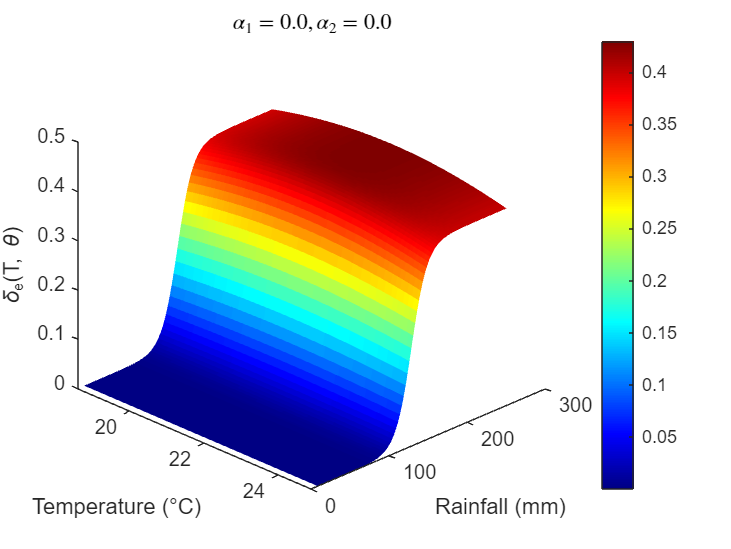

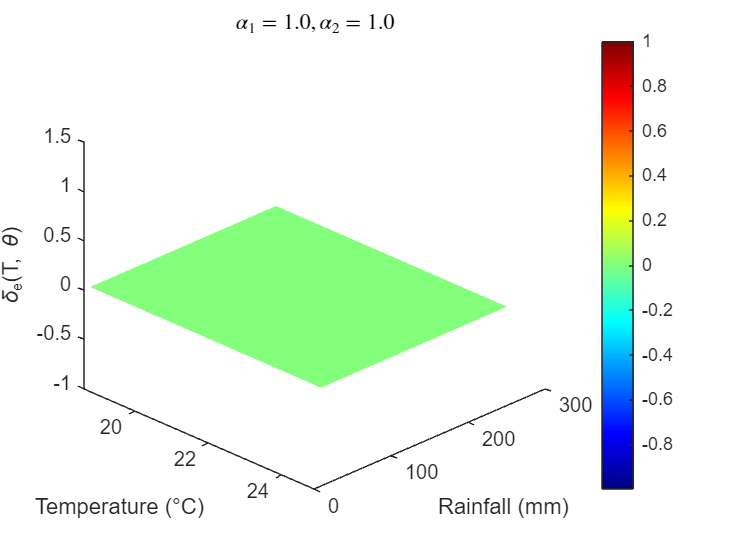

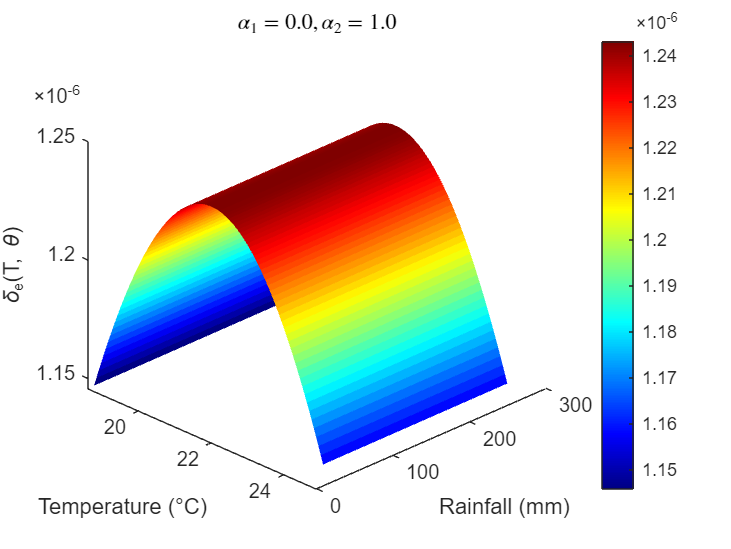

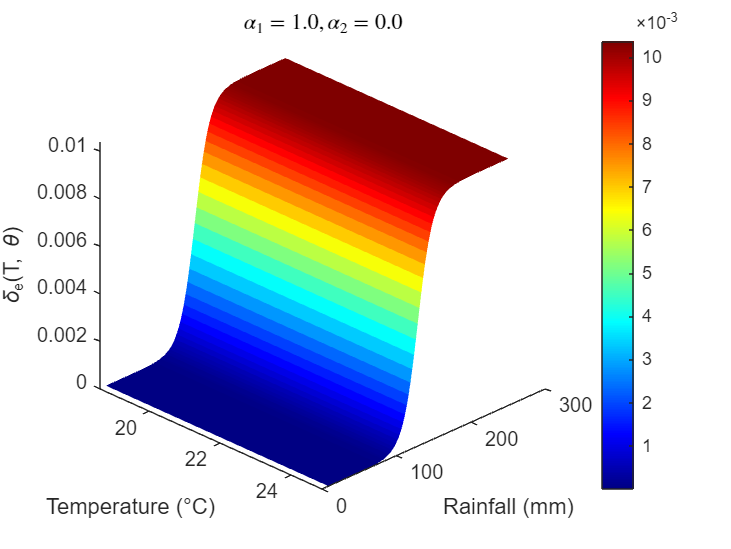

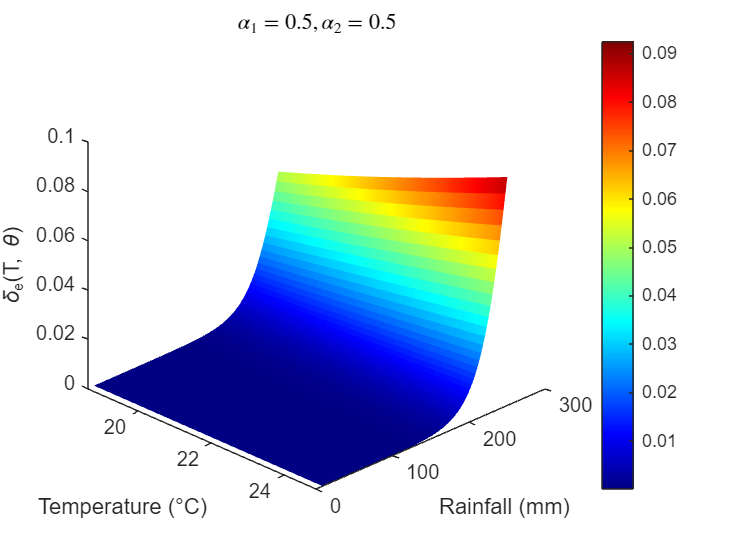


%% Define intervention cases [Shading u2, Mulching u3]
control_cases = [
    0, 0;     % No control
    1, 1;     % Full control
    0, 1;     % No shading, full mulching
    1, 0;     % Full shading, no mulching
    0.5, 0.5  % Both at 50%
];

%% Create a grid for Temperature and Rainfall
[T_grid, theta_grid] = meshgrid(linspace(min(T), max(T), 100), linspace(min(theta), max(theta), 100));

%% Loop through intervention/control cases
for i = 1:size(control_cases,1)
    u2_const = control_cases(i,1); % Shading
    u3_const = control_cases(i,2); % Mulching

    % Define constant control functions
    u2 = @(t) u2_const;
    u3 = @(t) u3_const;

    % Define beta_e as a function handle over the grid
    beta_e = @(t, T, H, theta) beta0 * exp( - ((1-u2(t))*T - T_opt).^2 / (2*sigma_T^2) ...
                                           - ((H - H_opt).^2) / sigma_H^2 ) ...
                               .* ( 1 ./ (1 + exp(-k2 * ((1-u3(t))*theta - theta_opt))) );

    % Evaluate beta_e at t = 0 for plotting
    beta_vals = beta_e(0, T_grid, H, theta_grid);

    %% Plot 3D surface for this control case
    figure;
    surf(T_grid, theta_grid, beta_vals, 'EdgeColor', 'none');
    colormap(jet);
    colorbar;
    hold on;

    % Highlight randomized optimal point
   % beta_opt = beta_e(0, T_opt, H, theta_opt);
    % plot3(T_opt, theta_opt, beta_opt, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
   % text(T_opt+0.1, theta_opt, beta_opt, ' Random Optimal \beta_e', 'Color', 'red', 'FontWeight', 'bold');

    xlabel('Temperature (°C)');
    ylabel('Rainfall (mm)');
    zlabel('\delta_e(T, \theta)');
    
    %title(sprintf('\\alpha_1= %.0f%%, \\alpha_2= %.0f%%', u2_const*100, u3_const*100));

    title(sprintf('$\\alpha_1 = %.1f, \\alpha_2 = %.1f$', u2_const, u3_const), ...
      'Interpreter', 'latex');

    view(45,30);
    grid off;   % <-- REMOVE GRID LINES
end